State Definition

[p0, p1] = deal(0.24,0.26);
[a0,b0,c0] = deal(0.79,4.5,1.74);
[a1,b1,c1] = deal(5.73,1.61,3.43);
psi0 = [cos(c0)*cos(a0),cos(c0)*sin(a0),sin(c0)*cos(b0),sin(c0)*sin(b0)];
psi1 = [cos(c1)*cos(a1),cos(c1)*sin(a1),sin(c1)*cos(b1),sin(c1)*sin(b1)];
psi2 = [cos(c0)*cos(a0),cos(c0)*sin(a0),-sin(c0)*cos(b0),-sin(c0)*sin(b0)];
psi3 = [cos(c1)*cos(a1),cos(c1)*sin(a1),-sin(c1)*cos(b1),-sin(c1)*sin(b1)];
RHO{1} = psi0.'*psi0;
RHO{2} = psi1.'*psi1;
RHO{3} = psi2.'*psi2;
RHO{4} = psi3.'*psi3;

Paper's guessing probability calculation


d = 0.01;
theta = 0:d:2*pi;
A0 = 0.5+(p0*sin(2*c0)*cos(theta-a0+b0)+p1*sin(2*c1)*cos(theta-a1+b1));
A1 = 0.5-(p0*sin(2*c0)*cos(theta+a0+b0)+p1*sin(2*c1)*cos(theta+a1+b1));
B0 = cos(c0)*sin(c1)*cos(theta-a0+b1)+sin(c0)*cos(c1)*cos(theta-a1+b0);
B1 = -(cos(c0)*sin(c1)*cos(theta+a0+b1)+sin(c0)*cos(c1)*cos(theta+a1+b0));
C = cos(c0)*cos(c1)*cos(a0-a1)+sin(c0)*sin(c1)*cos(b0-b1);
F0 = 0.5*(A0+sqrt(A0.^2-4*p0*p1*(B0+C).^2));
F1 = 0.5*(A1+sqrt(A1.^2-4*p0*p1*(B1+C).^2));
[F0max,ThetaF0max] = max(F0);
[F1max,ThetaF1max] = max(F1);

Plotting

hold all
F0plot = plot(theta,F1,'b');
plot(ThetaF1max*d,F1max,'bo')
F1plot = plot(theta,F0,'r');
fig = plot(ThetaF0max*d,F0max,'ro')

fig =   Line (data4) - 속성 있음:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 5.6400
              YData: 0.5398
              ZData: [1×0 double]

  모든 속성 표시


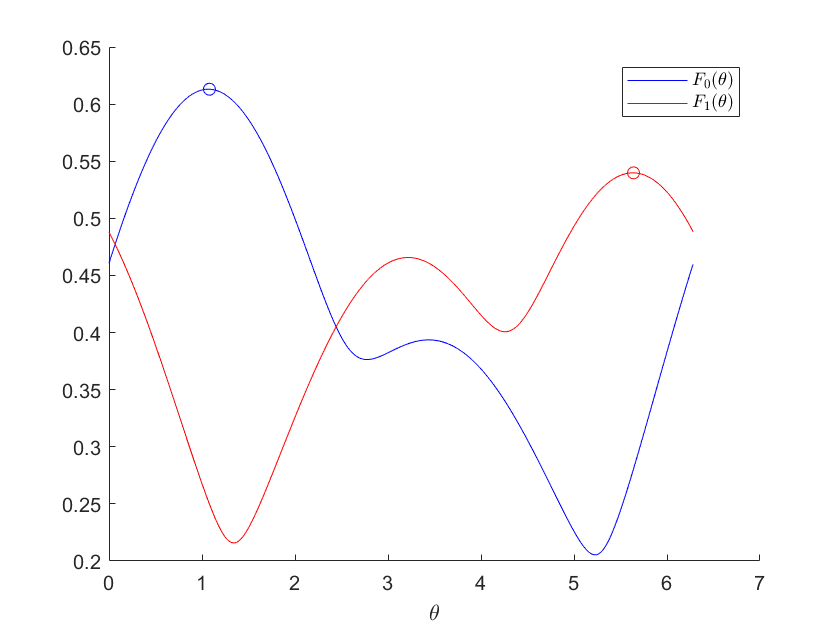

leg1 = legend([F0plot,F1plot],{'$F_0(\theta)$','$F_1(\theta)$'});
set(leg1,'Interpreter','latex');
xlabel('\theta')
saveas(fig,'4Pure_LI_Ensemble.png');

Verification

% [Pg,M,~] = MinErrorDiscrimination([p0,p1,p0,p1],RHO);
% P = M{1}+M{2};
% theta = asin(P(3,2)*2);
% A0 = 0.5+(p0*sin(2*c0)*cos(theta-a0+b0)+p1*sin(2*c1)*cos(theta-a1+b1));
% A1 = 0.5-(p0*sin(2*c0)*cos(theta+a0+b0)+p1*sin(2*c1)*cos(theta+a1+b1));
% B0 = cos(c0)*sin(c1)*cos(theta-a0+b1)+sin(c0)*cos(c1)*cos(theta-a1+b0);
% B1 = -(cos(c0)*sin(c1)*cos(theta+a0+b1)+sin(c0)*cos(c1)*cos(theta+a1+b0));
% C = cos(c0)*cos(c1)*cos(a0-a1)+sin(c0)*sin(c1)*cos(b0-b1);
% F0 = 0.5*(A0+sqrt(A0.^2-4*p0*p1*((B0+C)).^2));
% F1 = 0.5*(A1+sqrt(A1.^2-4*p0*p1*((B1+C)).^2));
% F1 = 0.5*A1+sqrt((0.5*A1).^2-4*p0*p1*((B1+C)/2).^2)
